%% for plots
set(groot,'defaultAxesTickLabelInterpreter','latex');  
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
set(groot,'defaultAxesFontSize',15)

%% input data
load('./input_data/RLambdaBoxCox.mat')
load('./input_data/keyfeaturesNHANEScohorts.mat')
load('./input_data/tableforsubstitution.mat')
load('./input_data/ALL_regressions.mat', 'nbins2rejectedcaloricintakeensWCDPI')
load('./input_data/trajectories')

logit = @(x) log(x./(1-x)); 
invlogit= @(y) exp(y) ./ (1 + exp(y));

## Number of Dishes in the Population (Survey Weights)

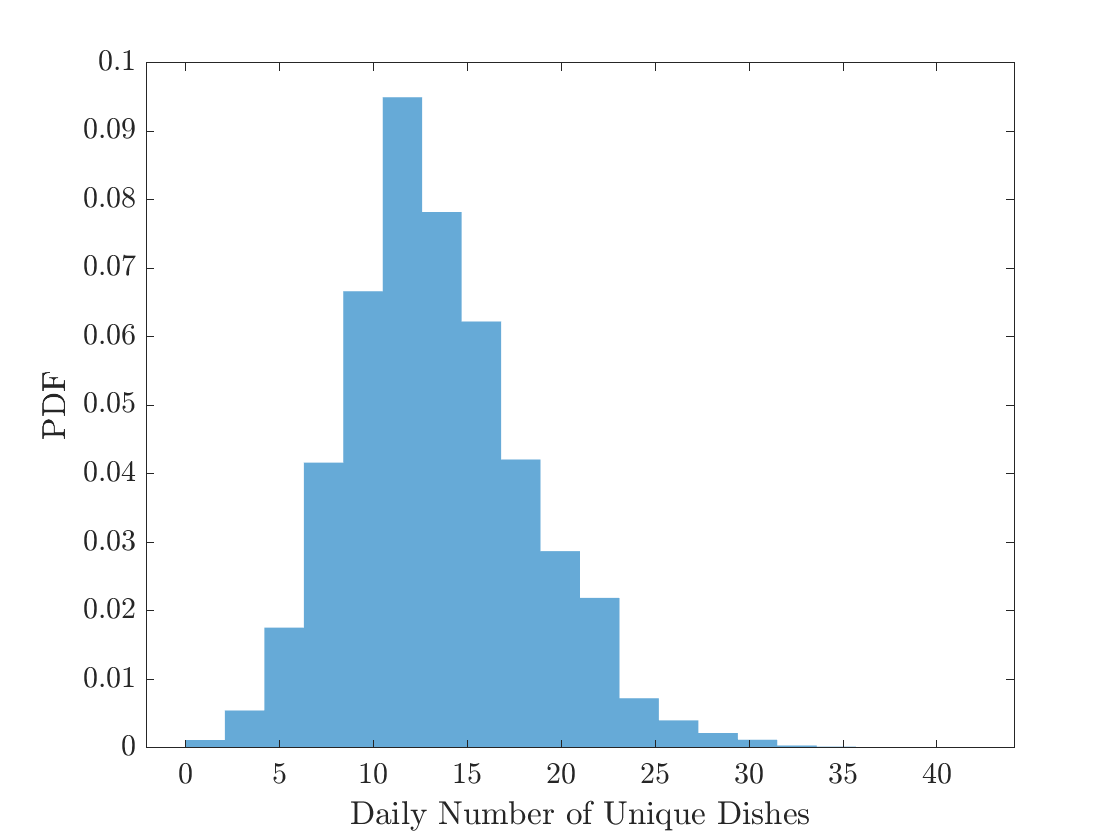

[newdata1]=whist(tableforsubstitution.num_unique_dishes./tableforsubstitution.NumDays, tableforsubstitution.WTMEC8YR);
figure,
histogram(newdata1,1, 'Normalization', 'PDF', 'NumBins', 20, 'EdgeColor','none');
xlabel('Daily Number of Unique Dishes')
ylabel('PDF')


ww=tableforsubstitution.WTMEC8YR/sum(tableforsubstitution.WTMEC8YR);
disp('Average Number of Daily Dishes')

Average Number of Daily Dishes


disp(sum(ww.*tableforsubstitution.num_unique_dishes))

   19.2827



## Population Caloric Intake (Survey Weights)

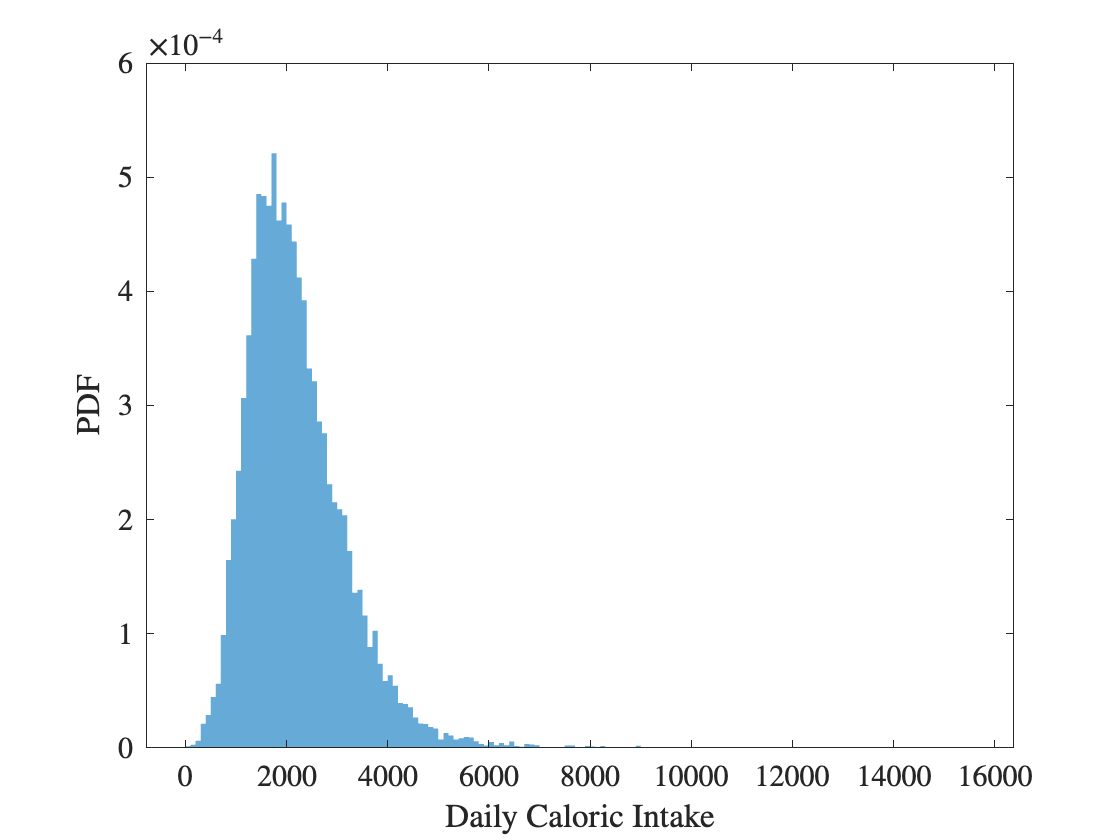

% h1=histogram(tableforsubstitution.Totalcaloriesconsumedmeanbothdays, 'Normalization', 'PDF', 'EdgeColor','none');
% Nb=h1.NumBins;
Nb=156;
[newdata1]=whist(tableforsubstitution.Totalcaloriesconsumedmeanbothdays, tableforsubstitution.WTMEC8YR);
figure,
histogram(newdata1, 'Normalization', 'PDF', 'NumBins', Nb, 'EdgeColor','none');
xlabel('Daily Caloric Intake')
ylabel('PDF')


ww=tableforsubstitution.WTMEC8YR/sum(tableforsubstitution.WTMEC8YR);
disp('Average Caloric Intake')

Average Caloric Intake


disp(sum(ww.*tableforsubstitution.Totalcaloriesconsumedmeanbothdays))

   2.1891e+03



## iFPro_{WC} histograms

disp('iFPro Histograms')

iFPro Histograms


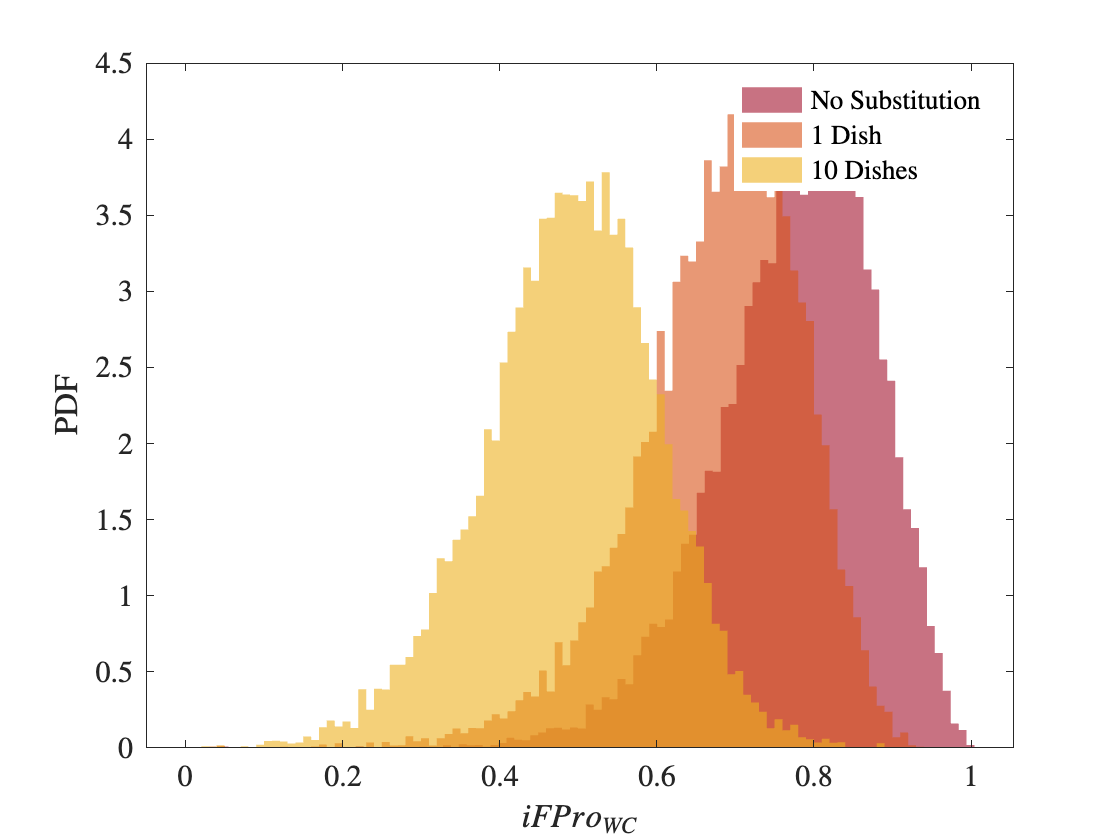

mat2use=FProCaloriesWWEIAtraj;
% figure,
% h1=histogram(mat2use(:,1), 'Normalization', 'PDF');
% hold on
% h2=histogram(mat2use(:,2), 'Normalization', 'PDF');
% hold on
% h3=histogram(mat2use(:,11), 'Normalization', 'PDF');

% Nb1=h1.NumBins;
% Nb2=h2.NumBins;
% Nb3=h3.NumBins;

Nb1=95;
Nb2=98;
Nb3=97;

[newdata1]=whist(mat2use(:,1), tableforsubstitution.WTMEC8YR);
[newdata2]=whist(mat2use(:,2), tableforsubstitution.WTMEC8YR);
[newdata3]=whist(mat2use(:,11), tableforsubstitution.WTMEC8YR);


figure,
histogram(newdata1, 'Normalization', 'PDF', 'NumBins', Nb1, 'EdgeColor', 'None', 'FaceColor', [0.64, 0.08, 0.18]);
hold on
histogram(newdata2, 'Normalization', 'PDF', 'NumBins', Nb2, 'EdgeColor', 'None');
hold on
histogram(newdata3, 'Normalization', 'PDF', 'NumBins', Nb3, 'EdgeColor', 'None');
xlabel('$iFPro_{WC}$')
ylabel('PDF')
ll=legend('No Substitution', '1 Dish', '10 Dishes');
ll.EdgeColor='None';


disp('Median No Substitution')

Median No Substitution


disp(median(newdata1))

    0.7872




disp('Median 1 Dish')

Median 1 Dish


disp(median(newdata2))

    0.6915



disp('Relative change')

Relative change


disp((median(newdata1)-median(newdata2))/median(newdata1))

    0.1215




disp('Median 10 Dish')

Median 10 Dish


disp(median(newdata3))

    0.4957



disp('Relative change')

Relative change


disp((median(newdata1)-median(newdata3))/median(newdata1))

    0.3703



## trajectories metabolic syndrome risk

disp('trajectories metabolic syndrome risk')

trajectories metabolic syndrome risk


tabcoef=nbins2rejectedcaloricintakeensWCDPI;

var2check='ens_FPro.WCDPI.mean.of.both.days.sum';
varinpython='FProCalories';
varinpythonsub='FProCalories_minWWEIA';
pheno='metabolic_syndrome';

ageDesignlambdaboxcoxcohortall.var=categorical(ageDesignlambdaboxcoxcohortall.var);
ageDesignlambdaboxcoxcohortall.resp_var=categorical(ageDesignlambdaboxcoxcohortall.resp_var);
tabcoef.var=categorical(tabcoef.var);

filtervar=((ageDesignlambdaboxcoxcohortall.var==var2check)&(ageDesignlambdaboxcoxcohortall.resp_var==pheno));
l=ageDesignlambdaboxcoxcohortall.lambda(filtervar);
disp('lambda for processing score')

lambda for processing score


disp(l)

     2




beta=tabcoef.coef(tabcoef.var==pheno);
disp(pheno)

metabolic_syndrome


disp('beta associated with processing score')

beta associated with processing score


disp(beta)

    0.1446



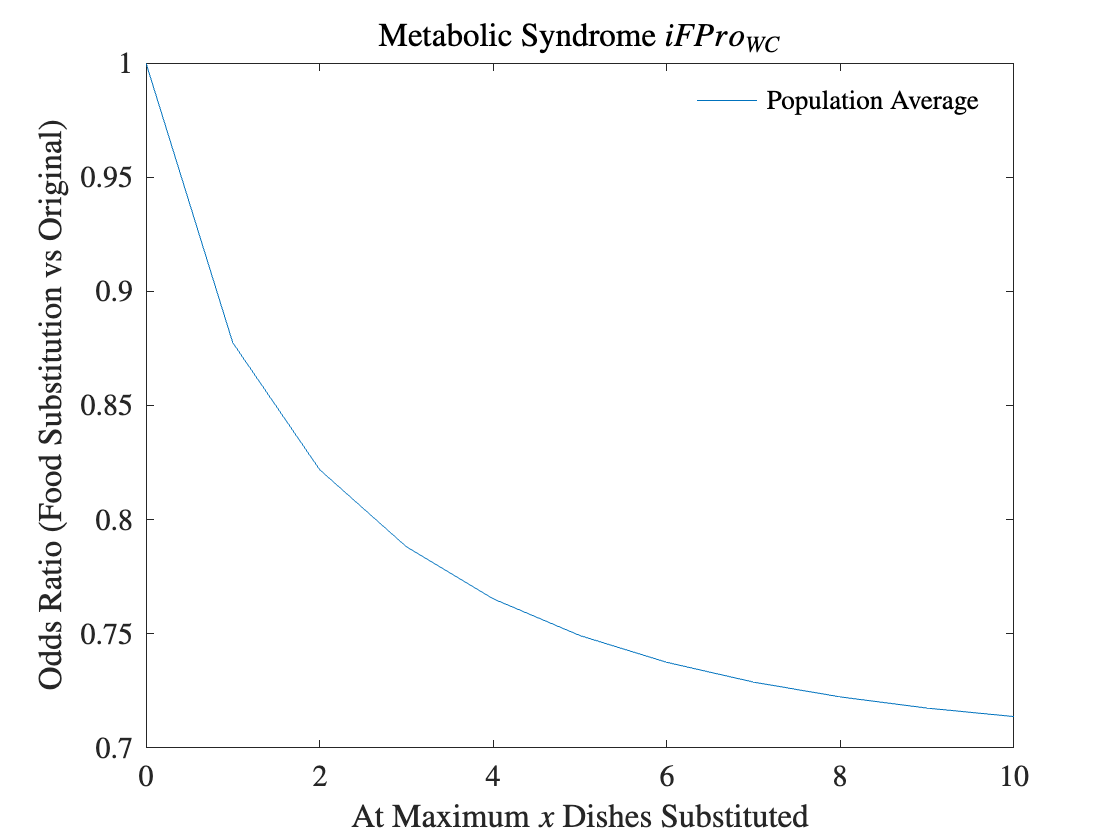



B=cell2mat( arrayfun(@(i) oddsratioEWAS(tableforsubstitution{:,varinpython},mat2use(:,i), beta, l) , 1:size(mat2use,2), 'uni',0) );
ww=tableforsubstitution.WTMEC8YR/sum(tableforsubstitution.WTMEC8YR);
wwt=repmat(ww,1, size(B,2));

figure, 
plot(0:(size(B,2)-1), sum(B.*wwt))
xlabel('At Maximum $x$ Dishes Substituted')
ylabel('Odds Ratio (Food Substitution vs Original)')
title('Metabolic Syndrome $iFPro_{WC}$')
ll=legend('Population Average');
ll.EdgeColor='None';
xlim([0, 10])
ylim([0.7, 1])

trace1=sum(B.*wwt);
disp('Relative change (1 dish)')

Relative change (1 dish)


disp(trace1(1)-trace1(2))

    0.1225



## trajectories Vitamin B-12

disp('trajectories Vitamin B-12')

trajectories Vitamin B-12



var2check='ens_FPro.WCDPI.mean.of.both.days.sum';
varinpython='FProCalories';
varinpythonsub='FProCalories_minWWEIA';
pheno='LBXB12';

filtervar=((ageDesignlambdaboxcoxcohortall.var==var2check)&(ageDesignlambdaboxcoxcohortall.resp_var==pheno));
l=ageDesignlambdaboxcoxcohortall.lambda(filtervar);
l=l(1);
disp('lambda for Processing Score')

lambda for Processing Score


disp(l)

     2





filtervar=((ageDesignlambdaboxcoxcohortall.var==pheno)&(ageDesignlambdaboxcoxcohortall.resp_var==pheno));
lexp=ageDesignlambdaboxcoxcohortall.lambda(filtervar);
lexp=lexp(1);
disp('lambda for Exposure')

lambda for Exposure


disp(lexp)

   -0.3000




beta=tabcoef.coef(tabcoef.var==pheno);
disp(pheno)

LBXB12


disp('beta associated with processing score')

beta associated with processing score


disp(beta)

   -0.1057



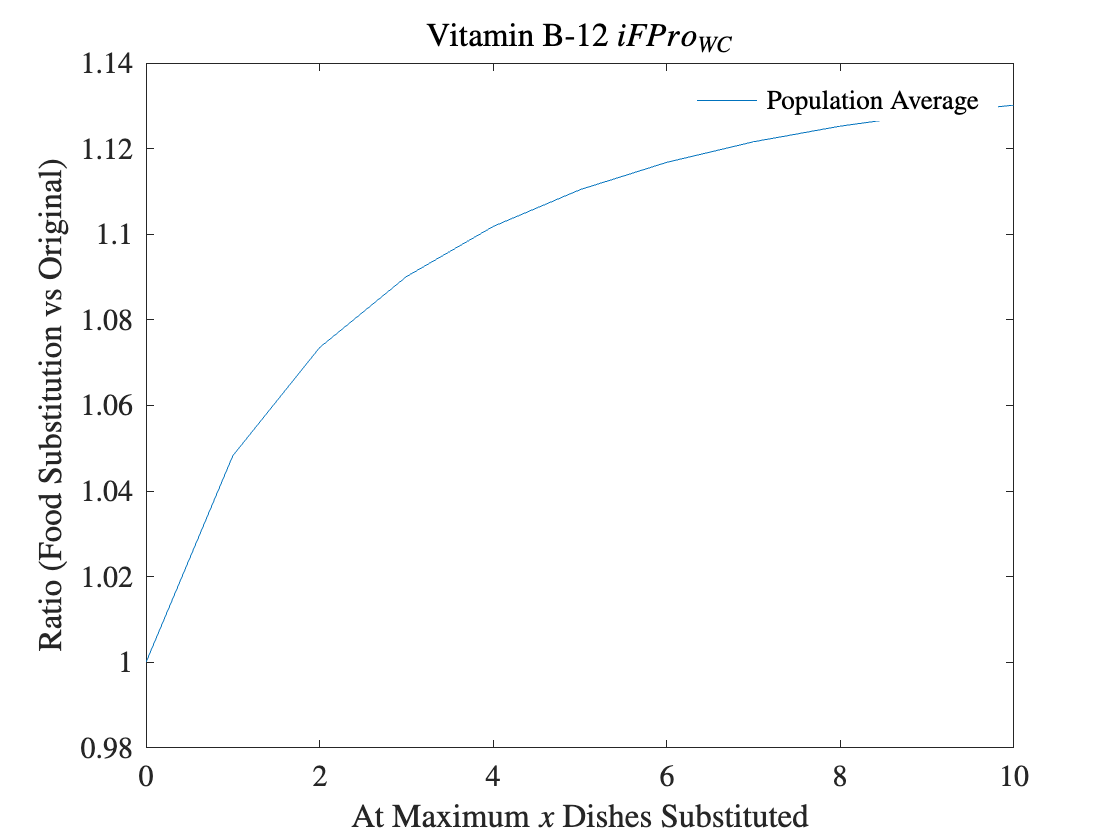


responsevar=tableforsubstitution{:,pheno};
B=cell2mat( arrayfun(@(i) generic_exposureEWAS(responsevar,tableforsubstitution{:,varinpython},mat2use(:,i), beta, l, lexp) , 1:size(mat2use,2), 'uni',0) );

Bnonan=B(~isnan(B(:,end)),:);
ww=tableforsubstitution.WTMEC8YR(~isnan(B(:,end)))/sum(tableforsubstitution.WTMEC8YR(~isnan(B(:,end))));
wwt=repmat(ww,1, size(Bnonan,2));


figure, 
plot(0:(size(Bnonan,2)-1), sum(Bnonan.*wwt))
xlabel('At Maximum $x$ Dishes Substituted')
ylabel('Ratio (Food Substitution vs Original)')
title('Vitamin B-12 $iFPro_{WC}$')
ll=legend('Population Average');
ll.EdgeColor='None';
xlim([0, 10])

trace2=sum(Bnonan.*wwt);

disp('Relative change (1 dish)')

Relative change (1 dish)


disp(trace2(1)-trace2(2))

   -0.0483



## trajectories Vitamin C

disp('trajectories Vitamin C')

trajectories Vitamin C


var2check='ens_FPro.WCDPI.mean.of.both.days.sum';
varinpython='FProCalories';
varinpythonsub='FProCalories_minWWEIA';
pheno='LBXVIC';

filtervar=((ageDesignlambdaboxcoxcohortall.var==var2check)&(ageDesignlambdaboxcoxcohortall.resp_var==pheno));
l=ageDesignlambdaboxcoxcohortall.lambda(filtervar);
l=l(1);
disp('lambda for Processing Score')

lambda for Processing Score


disp(l)

     2





filtervar=((ageDesignlambdaboxcoxcohortall.var==pheno)&(ageDesignlambdaboxcoxcohortall.resp_var==pheno));
lexp=ageDesignlambdaboxcoxcohortall.lambda(filtervar);
lexp=lexp(1);
disp('lambda for Exposure')

lambda for Exposure


disp(lexp)

    0.3000




beta=tabcoef.coef(tabcoef.var==pheno);
disp(pheno)

LBXVIC


disp('beta associated to processing score')

beta associated to processing score


disp(beta)

   -0.2125



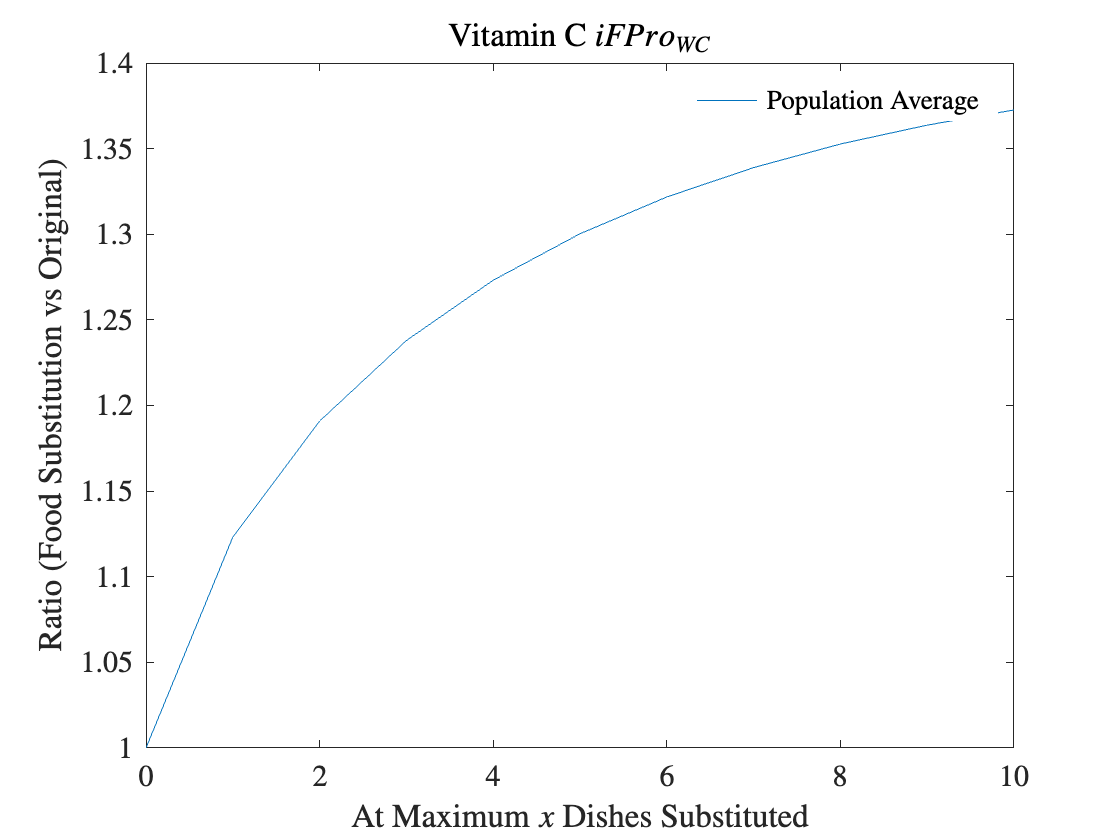


responsevar=tableforsubstitution{:,pheno};
B=cell2mat( arrayfun(@(i) generic_exposureEWAS(responsevar,tableforsubstitution{:,varinpython},mat2use(:,i), beta, l, lexp) , 1:size(mat2use,2), 'uni',0) );

Bnonan=B(~isnan(B(:,end)),:);
ww=tableforsubstitution.WTMEC8YR(~isnan(B(:,end)))/sum(tableforsubstitution.WTMEC8YR(~isnan(B(:,end))));
wwt=repmat(ww,1, size(Bnonan,2));

figure, 
plot(0:(size(Bnonan,2)-1), sum(Bnonan.*wwt))
xlabel('At Maximum $x$ Dishes Substituted')
ylabel('Ratio (Food Substitution vs Original)')
title('Vitamin C $iFPro_{WC}$')
ll=legend('Population Average');
ll.EdgeColor='None';
xlim([0, 10])

%ylim([0.7, 1])
trace3=sum(Bnonan.*wwt);


disp('Relative change (1 dish)')

Relative change (1 dish)


disp(trace3(1)-trace3(2))

   -0.1231



## trajectories Bisphenol A

disp('trajectories Bisphenol A')

trajectories Bisphenol A


var2check='ens_FPro.WCDPI.mean.of.both.days.sum';
varinpython='FProCalories';
varinpythonsub='FProCalories_minWWEIA';
pheno='URXBPH';

filtervar=((ageDesignlambdaboxcoxcohortall.var==var2check)&(ageDesignlambdaboxcoxcohortall.resp_var==pheno));
l=ageDesignlambdaboxcoxcohortall.lambda(filtervar);
l=l(1);
disp('lambda for Processing Score')

lambda for Processing Score


disp(l)

     2





filtervar=((ageDesignlambdaboxcoxcohortall.var==pheno)&(ageDesignlambdaboxcoxcohortall.resp_var==pheno));
lexp=ageDesignlambdaboxcoxcohortall.lambda(filtervar);
lexp=lexp(1);
disp('lambda for Exposure')

lambda for Exposure


disp(lexp)

   -0.4000




beta=tabcoef.coef(tabcoef.var==pheno);
disp(pheno)

URXBPH


disp('beta associated to processing score')

beta associated to processing score


disp(beta)

    0.0865



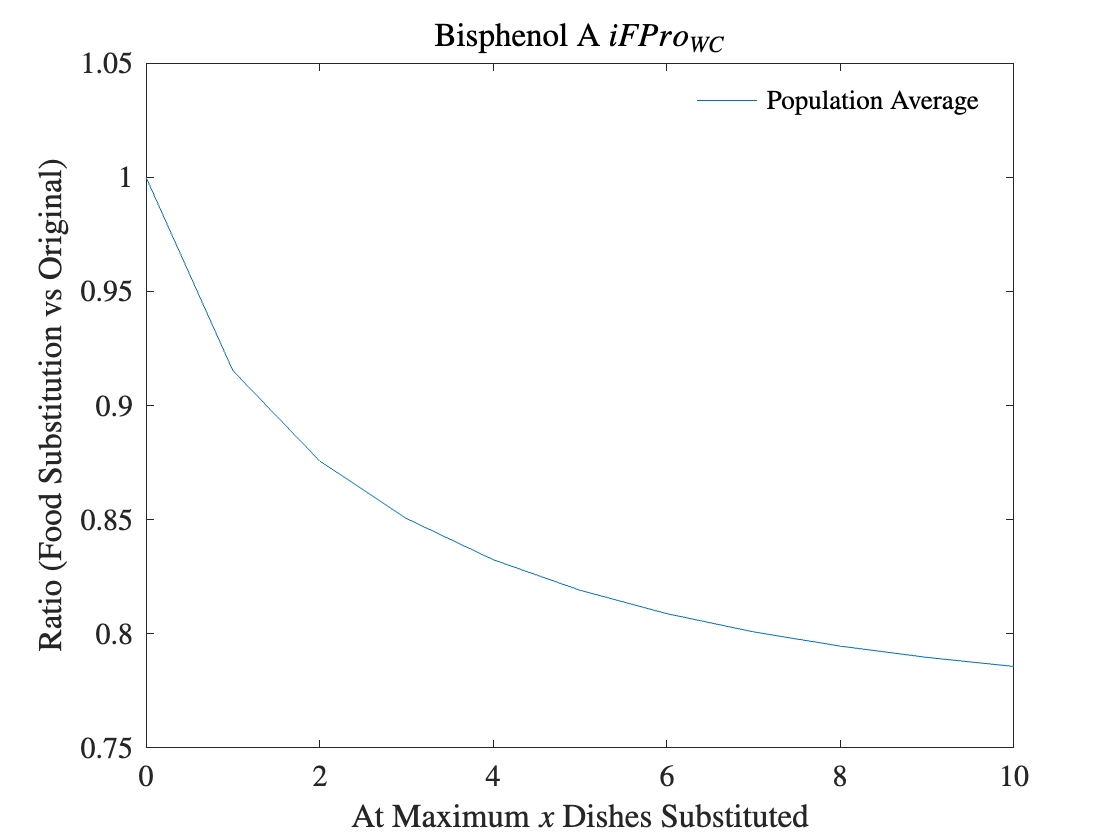


responsevar=tableforsubstitution{:,pheno};
B=cell2mat( arrayfun(@(i) generic_exposureEWAS(responsevar,tableforsubstitution{:,varinpython},mat2use(:,i), beta, l, lexp) , 1:size(mat2use,2), 'uni',0) );

Bnonan=B(~isnan(B(:,end)),:);
ww=tableforsubstitution.WTMEC8YR(~isnan(B(:,end)))/sum(tableforsubstitution.WTMEC8YR(~isnan(B(:,end))));
wwt=repmat(ww,1, size(Bnonan,2));

figure, 
plot(0:(size(Bnonan,2)-1), sum(Bnonan.*wwt))
xlabel('At Maximum $x$ Dishes Substituted')
ylabel('Ratio (Food Substitution vs Original)')
title('Bisphenol A $iFPro_{WC}$')
ll=legend('Population Average');
ll.EdgeColor='None';
xlim([0, 10])

trace4=sum(Bnonan.*wwt);


disp('Relative change (1 dish)')

Relative change (1 dish)


disp(trace4(1)-trace4(2))

    0.0847



## All together

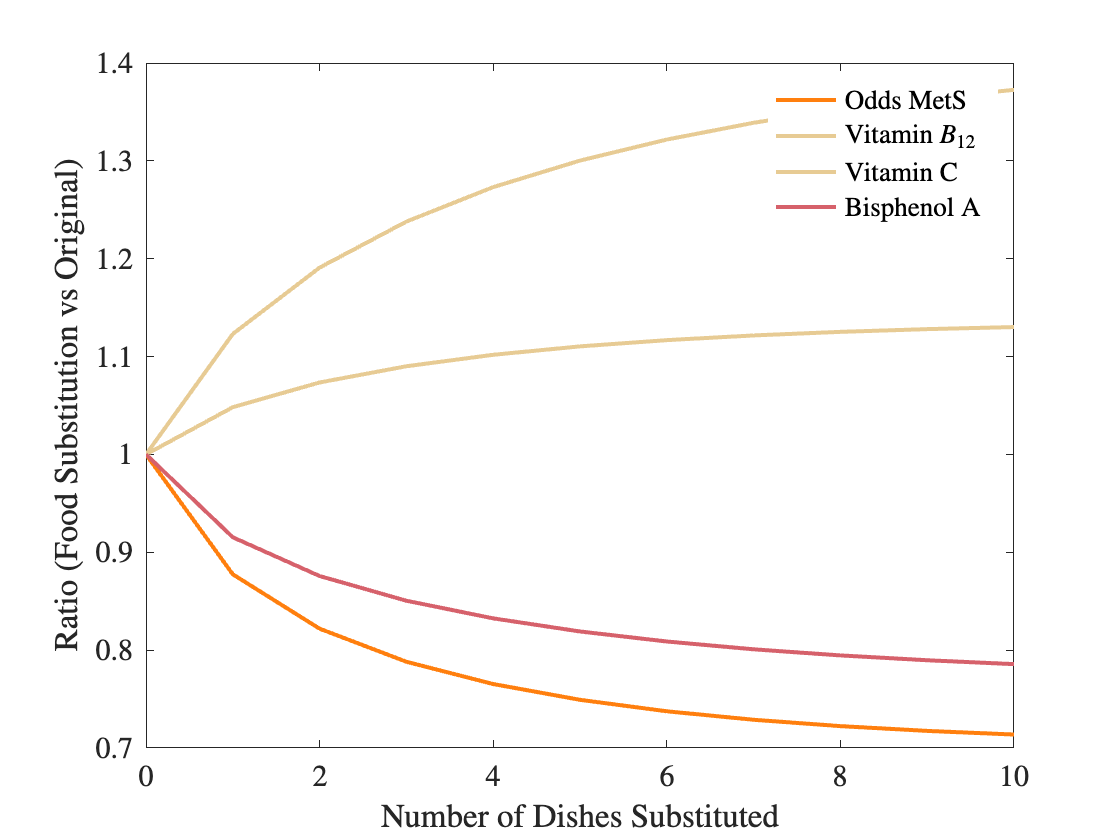

figure,
p1=plot(0:10, trace1(1:11), 'LineWidth', 2);
p1.Color=[1.0, 0.4980392156862745, 0.054901960784313725];

hold on
p2=plot(0:10, trace2(1:11), 'LineWidth', 2);
p2.Color=[0.9058823529411765, 0.796078431372549, 0.5803921568627451];

hold on
p3=plot(0:10, trace3(1:11), 'LineWidth', 2);
p3.Color=[0.9058823529411765, 0.796078431372549, 0.5803921568627451];

hold on
p4=plot(0:10, trace4(1:11), 'LineWidth', 2);
p4.Color=[0.8392156862745098, 0.3803921568627451, 0.4196078431372549];

xlabel('Number of Dishes Substituted')
ylabel('Ratio (Food Substitution vs Original)')
ll=legend('Odds MetS', 'Vitamin $B_{12}$', 'Vitamin C', 'Bisphenol A');
ll.EdgeColor='None';